clear; clc; close all;

1

zweipunkte(@f, 0.1, 0.6)

ans = 0.0330

dreiendpunkte(@f, 0.1, 0.6)

ans = 0.0388

dreimittelpunkte(@f, 0.1, 0.6)

ans = 0.0386

fuenfpunkte(@f, 0.1, 0.6)

ans = 0.0386

2

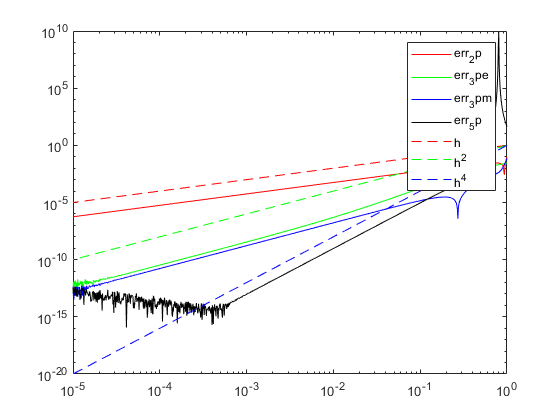

ploterrors(0.6);

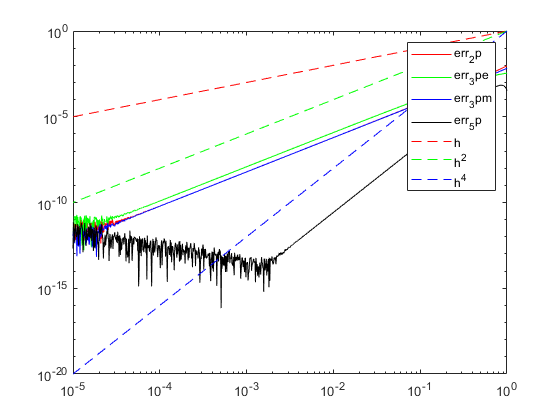

ploterrors(2.0);

function num = f(x)
    num = (x/(1+x))^5;
end

function num = fdot(x)
    num = (5*x^4)/(x + 1)^6;
end

function fdot = zweipunkte(f,h,x0)
    fdot = (f(x0)-f(x0-h))/h;
end

function fdot = dreiendpunkte(f,h,x0)
    fdot = (-3*f(x0)+4*f(x0+h)-f(x0+2*h))/(2*h);
end

function fdot = dreimittelpunkte(f,h,x0)
    fdot = (f(x0+h)-f(x0-h))/(2*h);
end

function fdot = fuenfpunkte(f,h,x0)
    fdot = (f(x0-2*h)-8*f(x0-h)+8*f(x0+h)-f(x0+2*h))/(12*h);
end

function ploterrors(x0)
    h_range = logspace(0,-5,1000);
    f_dot = ones(size(h_range)).*fdot(x0);
    res_2p = zeros(size(h_range));
    res_3pe = zeros(size(h_range));
    res_3pm = zeros(size(h_range));
    res_5p = zeros(size(h_range));
    for i=1:numel(h_range)
        h = h_range(i);
        res_2p(i) = zweipunkte(@f,h,x0);
        res_3pe(i) = dreiendpunkte(@f,h,x0);
        res_3pm(i) = dreimittelpunkte(@f,h,x0);
        res_5p(i) = fuenfpunkte(@f,h,x0);
    end
    err_2p = abs(f_dot-res_2p);
    err_3pe = abs(f_dot-res_3pe);
    err_3pm = abs(f_dot-res_3pm);
    err_5p = abs(f_dot-res_5p);
    g1 = h_range;
    g2 = h_range.^2;
    g3 = h_range.^4;
    loglog(h_range,err_2p,"r-",h_range,err_3pe,"g-",h_range,err_3pm,"b-",h_range,err_5p,"k-",h_range,g1,"r--",h_range,g2,"g--",h_range,g3,"b--");
    legend("err_2p","err_3pe","err_3pm","err_5p","h","h^2","h^4")
end